# Phase Potraits - Tutorial

clear
close all
clc

### Stable Node

Example 1

Consensus Problem for multi-agent :  Leader-Follower formation control

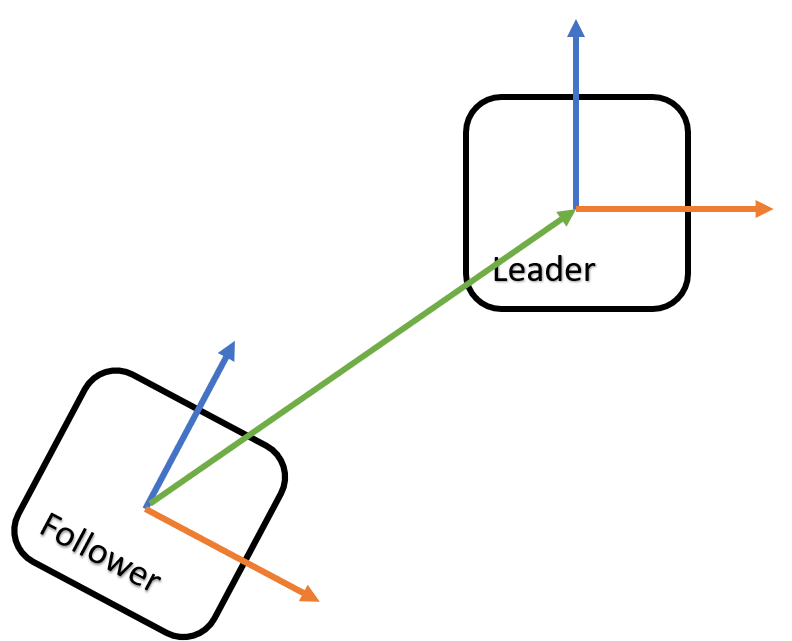


$$\frac{dx_1}{dt} = -k_1x_1;$$



$$\frac{dx_2}{dt} = k_1x_1 - k_2x_2$$


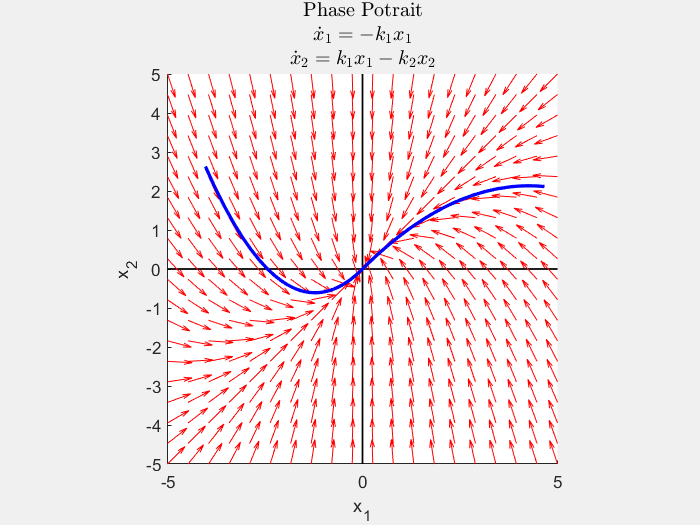

% settings
x1_lim = [-5 5]; % x-axis limit
x2_lim = [-5 5]; % y-axis limit
step_size = 20; % discretization factor

% options
options.vector_color = 'r'; % arrow color
options.xlabel = 'x_1';
options.ylabel = 'x_2';
options.title = ["Phase Potrait", "$\dot{x}_1 = -k_1 x_1$", "$\dot{x}_2 = k_1 x_1 - k_2 x_2$"]; % multi-line title
options.title_Fontsize = 12;

options.equal_size_vectors = 1;
options.trajectories.tend = 50; % time [0 tend] for the duration of the trajectory
options.trajectories.traj_color = 'b'; % color of the trajectory
options.trajectories.plotTraj = true; % to plot the user input trajectory
options.trajectories.numTraj = 2; % will only be used if above statement is true
options.trajectories.plotArrow = false; % to plot the directions of the trajectory
options.trajectories.numArrows = 0; % will only be used if above statement is true
options.trajectories.lineWidth = 2;

% function definition
k_1 = 0.21;
k_2 = 0.42;
f = @(t,X) ([-k_1*X(1); k_1*X(1) - k_2*X(2)]);

% phase potraint -> return figure handle
fig = phasePotrait(f, x1_lim, x2_lim, step_size, options);

### Unstable Node

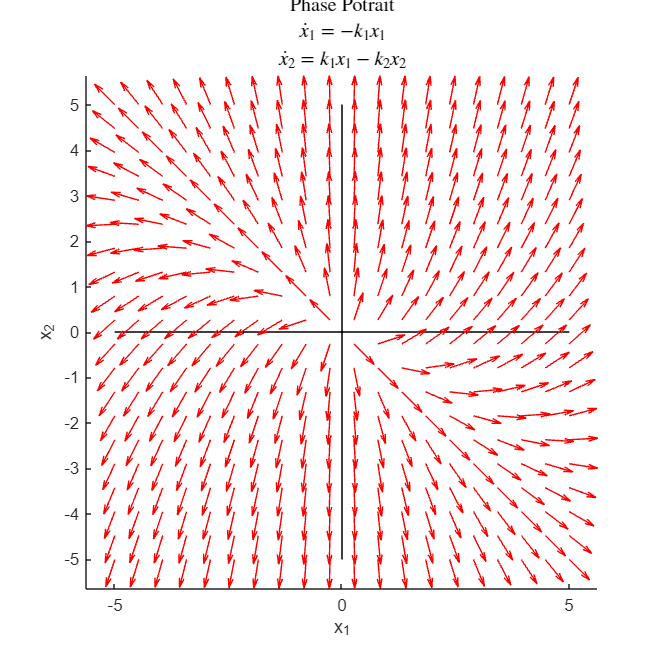

k_1 = 0.21;
k_2 = -0.42;
f = @(t,X) ([k_1*X(1); k_1*X(1) - k_2*X(2)]);
options.trajectories.plotTraj = false; % to plot the user input trajectory
options.trajectories.numTraj = 2; % will only be used if above statement is true
options.trajectories.plotArrow = false; % to plot the directions of the trajectory
options.trajectories.numArrows = 0; % will only be used if above statement is true
options.trajectories.lineWidth = 2;
h = phasePotrait(f,x1_lim,x2_lim,step_size,options);
h.Position = [351.4000 47.4000 528.8000 530.4000];
hold off

### Saddle Node


$$\frac{dx_1}{dt} = -k_1x_1;\;
\frac{dx_2}{dt} = k_1x_1 + k_2x_2$$


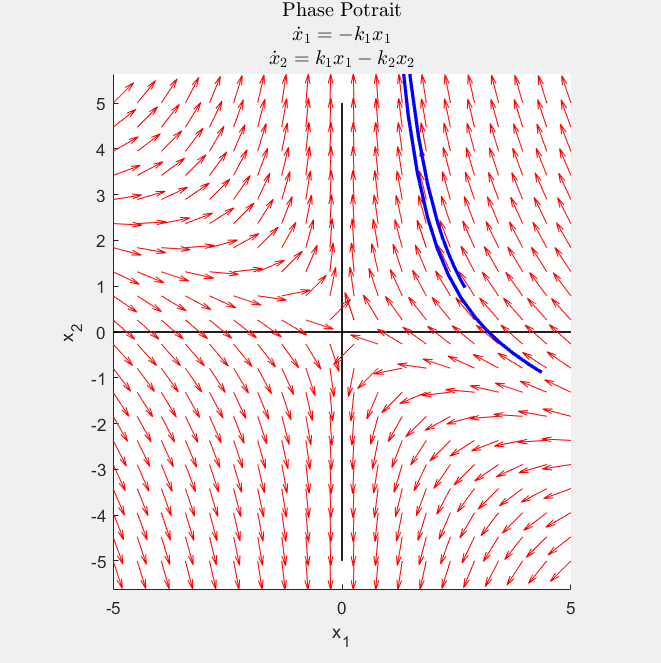

k_1 = 0.21;
k_2 = 0.42;
f = @(t,X) ([-k_1*X(1); k_1*X(1) + k_2*X(2)]);
options.trajectories.plotTraj = false; % to plot the user input trajectory
options.trajectories.numTraj = 2; % will only be used if above statement is true
options.trajectories.plotArrow = false; % to plot the directions of the trajectory
options.trajectories.numArrows = 0; % will only be used if above statement is true
options.trajectories.lineWidth = 2;
h = phasePotrait(f,x1_lim,x2_lim,step_size,options);
h.Position = [351.4000 47.4000 528.8000 530.4000];
axis equal
hold off

### Center

Example Simple Harmonic Motion

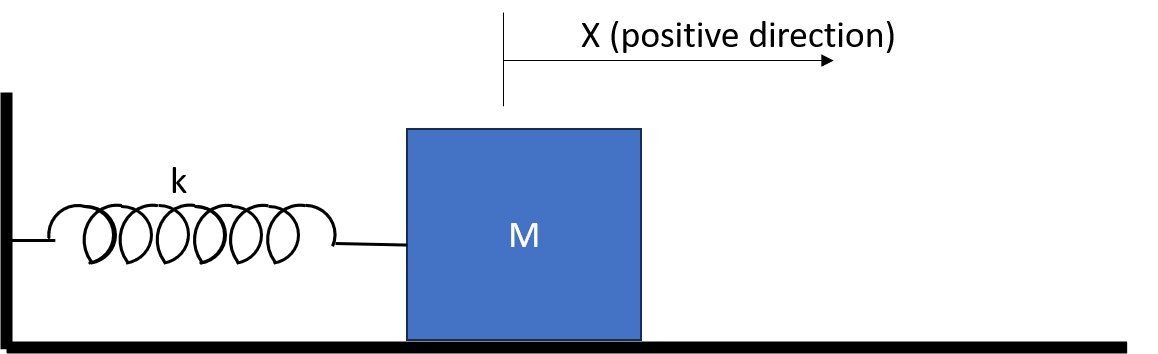


$$m\ddot{x} + kx = 0$$


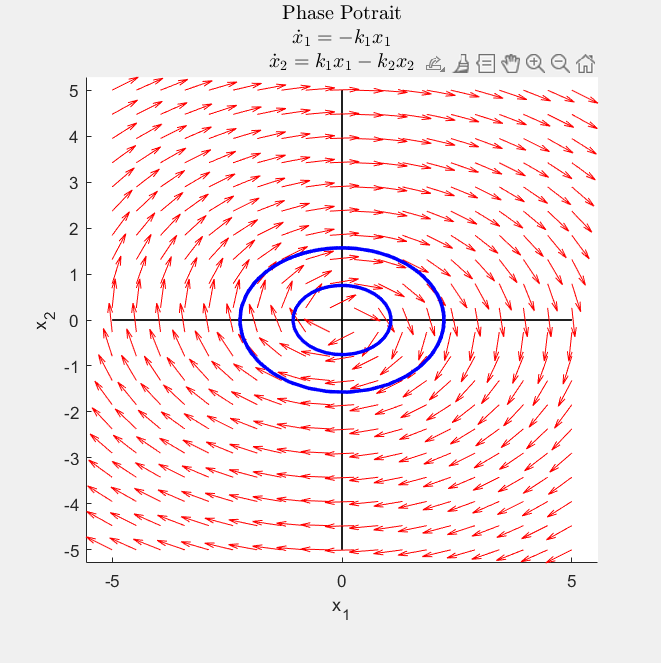

m = 1;
k = 0.5;
f = @(t,x) ([0 1; -k/m 0]*x);
options.trajectories.plotTraj = false; % to plot the user input trajectory
options.trajectories.numTraj = 2; % will only be used if above statement is true
options.trajectories.plotArrow = false; % to plot the directions of the trajectory
options.trajectories.numArrows = 0; % will only be used if above statement is true
options.trajectories.lineWidth = 2;
h = phasePotrait(f,x1_lim,x2_lim,step_size,options);
h.Position = [351.4000 47.4000 528.8000 530.4000];

### Stable Focus

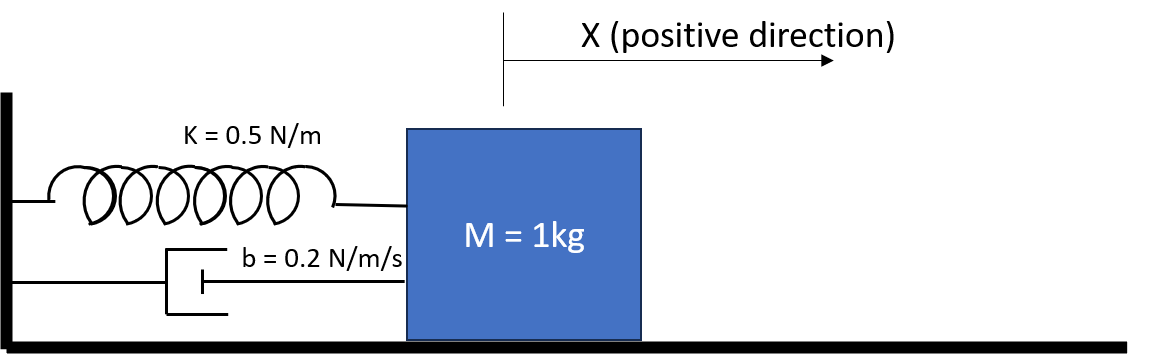

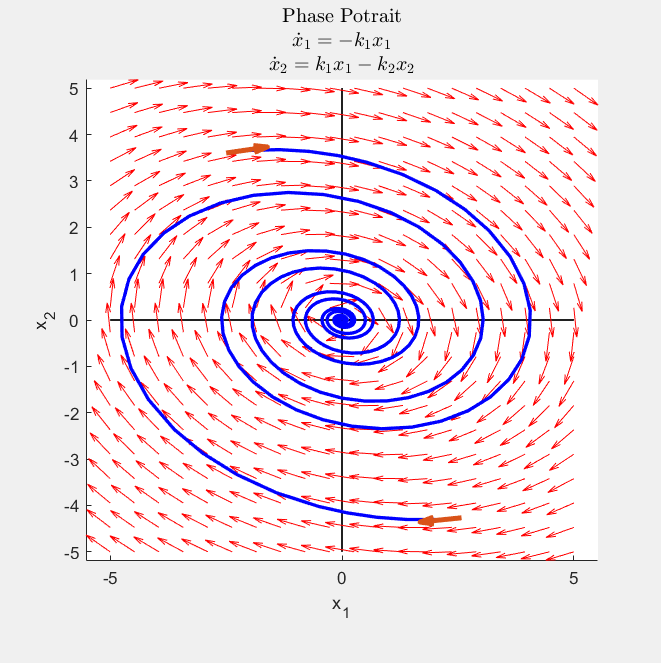

m = 1;
k = 0.5;
b = 0.2;
f = @(t,x) ([0 1; -k/m -b/m]*x);
options.trajectories.plotTraj = true; % to plot the user input trajectory
options.trajectories.numTraj = 2; % will only be used if above statement is true
options.trajectories.plotArrow = true; % to plot the directions of the trajectory 
options.trajectories.numArrows = 0; % will only be used if above statement is true
options.trajectories.lineWidth = 2;
h = phasePotrait(f,x1_lim,x2_lim,step_size,options);
h.Position = [351.4000 47.4000 528.8000 530.4000];

### Unstable Focus

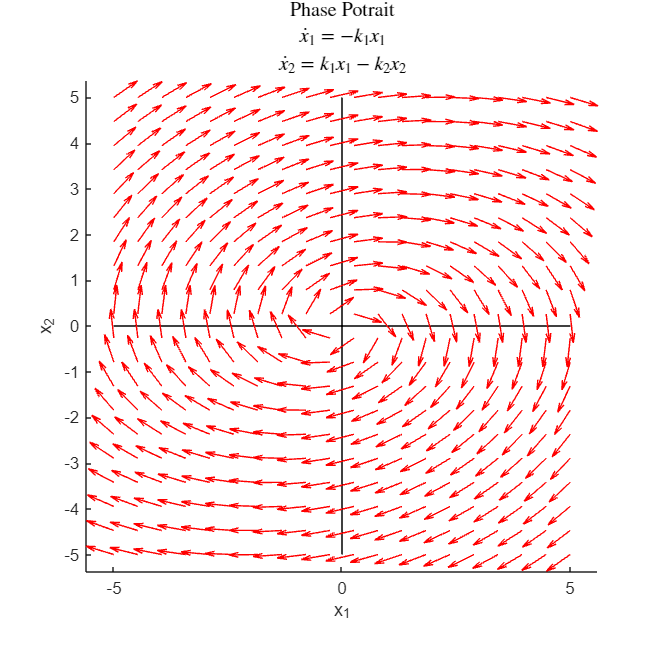

m = 1;
k = 0.5;
b = -0.2;
f = @(t,x) ([0 1; -k/m -b/m]*x);
options.equal_size_vectors = 1;
options.trajectories.plotTraj = false;
h = phasePotrait(f,x1_lim,x2_lim,step_size,options);
h.Position = [351.4000 47.4000 528.8000 530.4000];

### Multiple Equillibria 

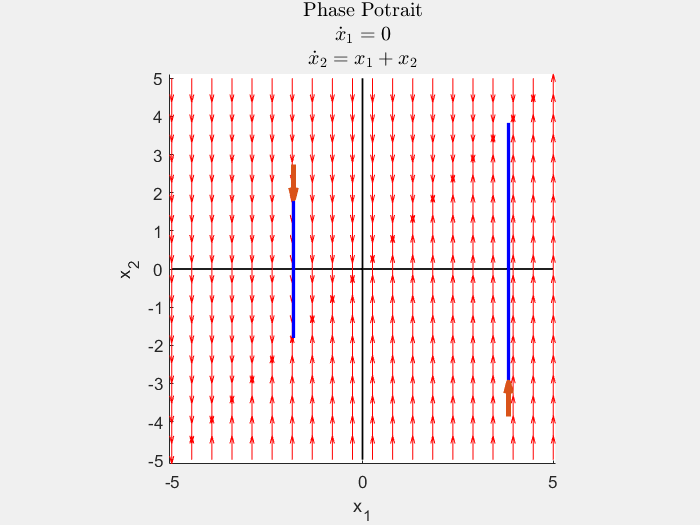

% settings
x1_lim = [-5 5]; % x-axis limit
x2_lim = [-5 5]; % y-axis limit
step_size = 20; % discretization factor

% options
options.vector_color = 'r'; % arrow color
options.xlabel = 'x_1';
options.ylabel = 'x_2';
options.title = ["Phase Potrait", "$\dot{x}_1 = 0 $", "$\dot{x}_2 = x_1 + x_2$"]; % multi-line title
options.title_Fontsize = 12;

options.equal_size_vectors = false;
options.trajectories.tend = 50; % time [0 tend] for the duration of the trajectory
options.trajectories.traj_color = 'b'; % color of the trajectory
options.trajectories.plotTraj = true; % to plot the user input trajectory
options.trajectories.numTraj = 2; % will only be used if above statement is true
options.trajectories.plotArrow = true; % to plot the directions of the trajectory
options.trajectories.numArrows = 0; % will only be used if above statement is true
options.trajectories.lineWidth = 2;

% function definition
k = -1;
f = @(t,X) ([0 ; X(1) + k*X(2)]);

% phase potraint -> return figure handle
fig = phasePotrait(f, x1_lim, x2_lim, step_size, options);

### Parametric Changes

Example:

Romeo and Juliet


$$\dot{R} = aR + bJ
$$



$$\dot{J} = cR + dJ$$


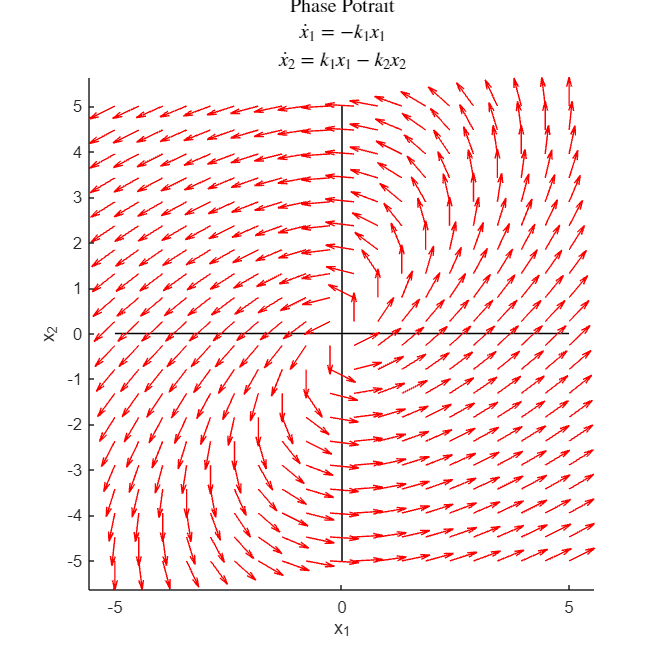

a = 2;
b = -2;
c = 2;
d = 0;
f = @(t,x) ([a b; c d]*x);
options.trajectories.plotTraj = false;
h = phasePotrait(f,x1_lim,x2_lim,step_size,options);
h.Position = [351.4000 47.4000 528.8000 530.4000];